# generateSignalDesignMatrixFromTraceProperties sample script

Just run the function without any arguments to see an example return value.

signal_design_matrix = mus1.SignalUtil.generateSignalDesignMatrixFromTraceProperties;
disp(signal_design_matrix)

     0     2     0
     5     8     2
    10    13     5
    16    18     3
    21    23     0



The returned signal design matrix can be passed to the `getXYVectorsFromSignalDesignMatrix` function, which returns X and Y vectors, which can be used for visualization or used as the parameters of a lookup table.

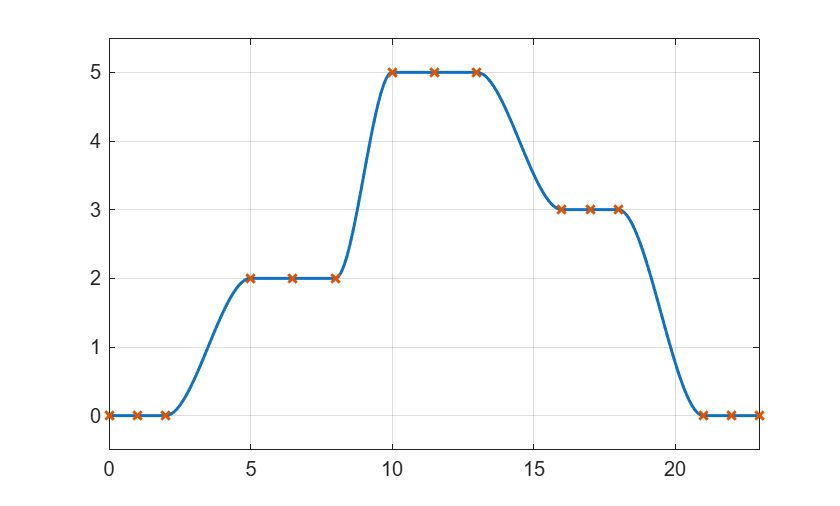

data_table = mus1.SignalUtil.getVectorsFromSignalDesignMatrix(signal_design_matrix);
mus1.SignalUtil.plotLookupTable1D(data_table.X, data_table.F)

Specify options.

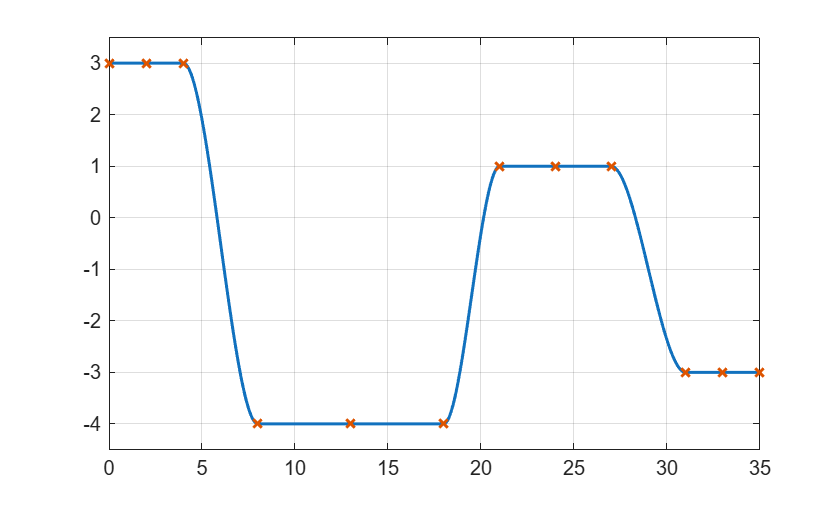

signal_design_matrix = mus1.SignalUtil.generateSignalDesignMatrixFromTraceProperties(...
  RandomSeed = 6, ... Random seed
  ...
  FInitialValue = 3, ... Initial data value
  XInitialFlatLength = 4, ... Initial constant duration
  XInitialTransitionLength = 4, ... Initial transition duration
  ...
  NumTransitions = 1, ... Number of transitions
  TransitionXRange = [2 5], ... Range of transition duration
  FlatXRange = [6 10], ... Range of constant duration
  FRange = [-4 4], ... Range of data value
  ...
  XFinalTransitionLength = 4, ... Final transition duration
  FFinalValue = -3, ... Final data value
  XFinalFlatLength = 4 );  % Final constant duration

data_table = mus1.SignalUtil.getVectorsFromSignalDesignMatrix(signal_design_matrix);

mus1.SignalUtil.plotLookupTable1D(data_table.X, data_table.F, ...
  Interpolation="Smooth", InterpolationInterval=0.1)

Simulate the "High Speed" drive pattern which is defined in the vehicle speed reference component of the BEV project.

signal_design_matrix = mus1.SignalUtil.generateSignalDesignMatrixFromTraceProperties(...
  RandomSeed = 6, ... Random seed
  ...
  FInitialValue = 0, ... Initial data value
  XInitialFlatLength = 10, ... Initial constant duration
  XInitialTransitionLength = 10, ... Initial transition duration
  ...
  NumTransitions = 10, ... Number of transitions
  TransitionXRange = [5 10], ... Range of transition duration
  FlatXRange = [5 10], ... Range of constant duration
  FRange = [60 100], ... Range of data value
  ...
  XFinalTransitionLength = 15, ... Final transition duration
  FFinalValue = 0, ... Final data value
  XFinalFlatLength = 10 );  % Final constant duration

disp(signal_design_matrix)

     0    10     0
    20    29    92
    35    43    90
    52    60    89
    65    73    82
    78    88    65
    96   105    99
   113   120    76
   127   137    68
   144   153    89
   161   166   100
   173   182    70
   197   207     0



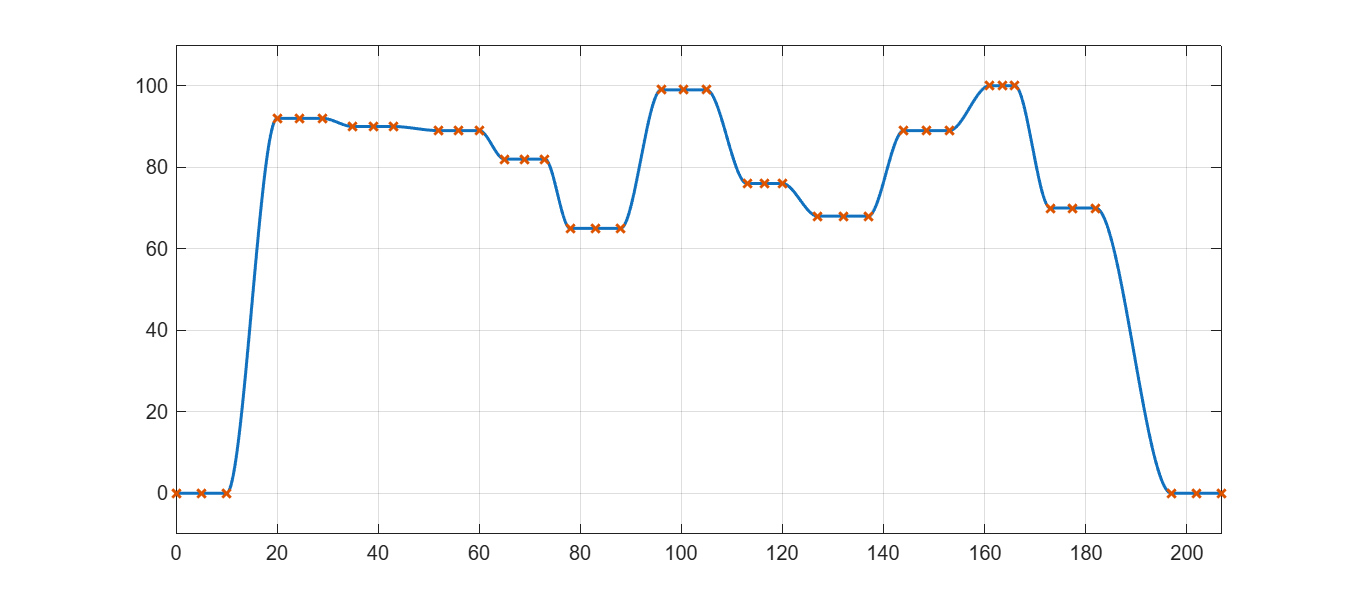

data_table = mus1.SignalUtil.getVectorsFromSignalDesignMatrix(signal_design_matrix);

fig = figure;
fig.Position(3:4) = [900 400];  % width height
mus1.SignalUtil.plotLookupTable1D(data_table.X, data_table.F, ...
  Interpolation="Smooth", InterpolationInterval=0.1, ...
  ParentAxes=axes(fig))

*Copyright 2025-2026 The MathWorks, Inc.*